# **Lab 2 - Semnale, Evolutie, Raspuns - Recapitulare**

clear
close all
clc

A = [19 9 -9 -16;
     7 1 -7 2;
     16 0 -6 -14;
     8 8 -8 -6];

B = [5;
     3;
     2;
     3];

C = [-1 0 2 2];

D = 5;

disp('Este sistemul stabil?');

Este sistemul stabil?


disp(eig(A));

  -6.0000 + 0.0000i
  -6.0000 - 0.0000i
  10.0000 + 0.0000i
  10.0000 + 0.0000i



Sistemul nu este stabil

T = ss(A,B,C,D)


T =
 
  A = 
        x1   x2   x3   x4
   x1   19    9   -9  -16
   x2    7    1   -7    2
   x3   16    0   -6  -14
   x4    8    8   -8   -6
 
  B = 
       u1
   x1   5
   x2   3
   x3   2
   x4   3
 
  C = 
       x1  x2  x3  x4
   y1  -1   0   2   2
 
  D = 
       u1
   y1   5
 
Continuous-time state-space model.


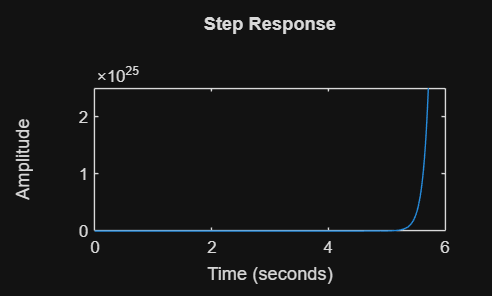


figure
step(T)

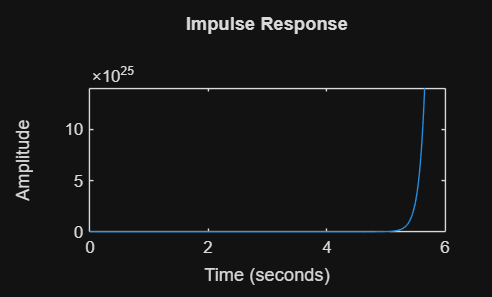


figure
impulse(T)


t = 0:0.01:20;

[wn, zeta, p] = damp(T)

wn =     6.0000
    6.0000
   10.0000
   10.0000


zeta =      1
     1
    -1
    -1


p =   -6.0000 + 0.0000i
  -6.0000 - 0.0000i
  10.0000 + 0.0000i
  10.0000 + 0.0000i



x_1 = [1;
       1;
       1;
       1]

x_1 =      1
     1
     1
     1



x_l = expm(A)

x_l = 1.0e+04 *

    5.5066    3.3040   -3.3040   -2.2026
    1.1013    1.1013   -1.1013    0.0000
    4.4053    2.2026   -2.2026   -2.2026
    1.1013    1.1013   -1.1013    0.0000


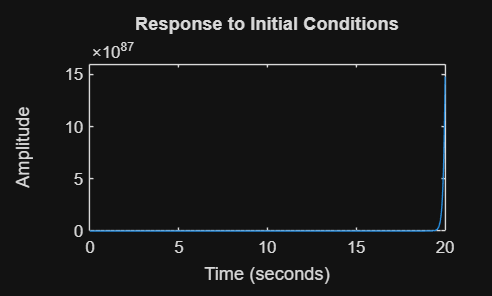


figure
initial(T,x_1,t)

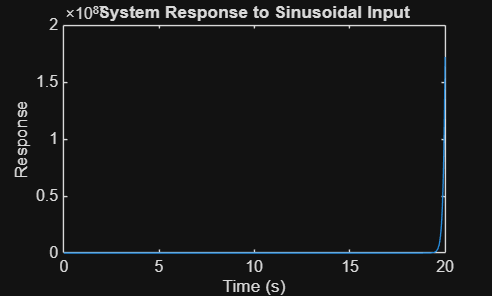


u2 = sin(2*t) .* double(t >= 0);

y = lsim(T, u2, t);
figure
plot(t, y);
xlabel('Time (s)');
ylabel('Response');
title('System Response to Sinusoidal Input');


T_min = ss(T,'min')


T_min =
 
  A = 
           x1      x2
   x1   9.371  0.2585
   x2   -1.53   10.63
 
  B = 
           u1
   x1  -2.506
   x2   6.381
 
  C = 
             x1        x2
   y1  -0.02366    0.7742
 
  D = 
       u1
   y1   5
 
Continuous-time state-space model.


disp('Este sistemul stabil?');

Este sistemul stabil?


disp(eig(T_min.A))

   10.0000
   10.0000




F = -acker(T_min.A,T_min.B,[-2 -2])

F =   -18.1511  -10.8875



disp(eig(T_min.A + T_min.B*F))

  -2.0000 + 0.0000i
  -2.0000 - 0.0000i




T_st = ss(T_min.A + T_min.B * F, T_min.B, T_min.C, T_min.D)


T_st =
 
  A = 
           x1      x2
   x1   54.85   27.54
   x2  -117.4  -58.85
 
  B = 
           u1
   x1  -2.506
   x2   6.381
 
  C = 
             x1        x2
   y1  -0.02366    0.7742
 
  D = 
       u1
   y1   5
 
Continuous-time state-space model.



tf(T_st)


ans =
 
  5 s^2 + 25 s - 24
  -----------------
    s^2 + 4 s + 4
 
Continuous-time transfer function.


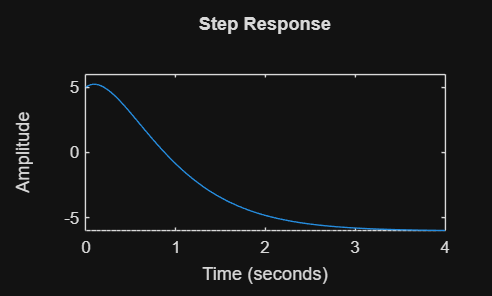


figure
step(T_st)

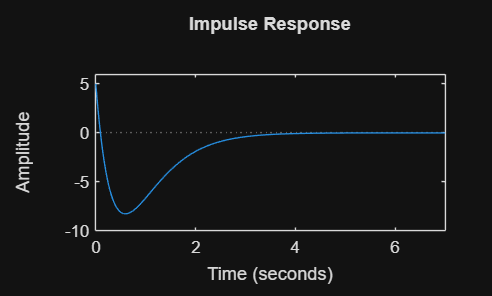


figure
impulse(T_st)

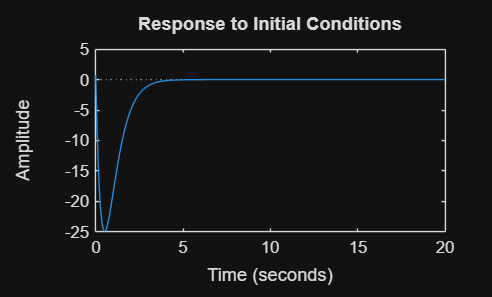


X_1st = [1;
         1];

figure
initial(T_st,X_1st,t)

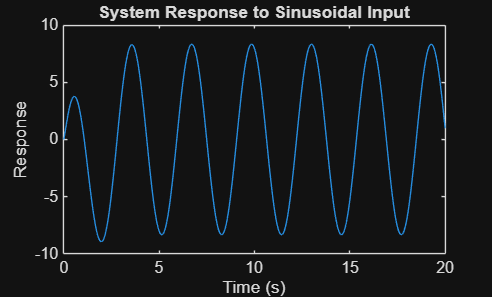


y = lsim(T_st, u2, t);
figure
plot(t, y);
xlabel('Time (s)');
ylabel('Response');
title('System Response to Sinusoidal Input');

PID la siso

clear
close all
clc

A = [19 9 -9 -16;
     7 1 -7 2;
     16 0 -6 -14;
     8 8 -8 -6];

B = [5;
     3;
     2;
     3];

C = [-1 0 2 2];

D = 5;

T = ss(A,B,C,D);

T_tf = tf(T)


T_tf =
 
  5 s^4 - 35 s^3 - 504 s^2 + 2052 s + 1.642e04
  --------------------------------------------
      s^4 - 8 s^3 - 104 s^2 + 480 s + 3600
 
Continuous-time transfer function.



pidtune(T_tf, 'PID')


ans =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.00767, Ki = 6.71e-05, Kd = 0.219
 
Continuous-time PID controller in parallel form.


Ala MIMO

clear
close all
clc

A = [19 9 -9 -16;
     7 1 -7 2;
     16 0 -6 -14;
     8 8 -8 -6];

B = [5 1;
     3 0;
     2 1;
     3 0];

C = [-1 0 2 2;
      0 1 0 0];

D = eye(2);

disp('Este sistemul stabil?');

Este sistemul stabil?


disp(eig(A));

  -6.0000 + 0.0000i
  -6.0000 - 0.0000i
  10.0000 + 0.0000i
  10.0000 + 0.0000i




T = ss(A,B,C,D)


T =
 
  A = 
        x1   x2   x3   x4
   x1   19    9   -9  -16
   x2    7    1   -7    2
   x3   16    0   -6  -14
   x4    8    8   -8   -6
 
  B = 
       u1  u2
   x1   5   1
   x2   3   0
   x3   2   1
   x4   3   0
 
  C = 
       x1  x2  x3  x4
   y1  -1   0   2   2
   y2   0   1   0   0
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.


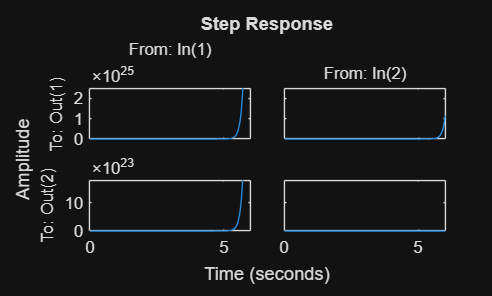


figure
step(T)

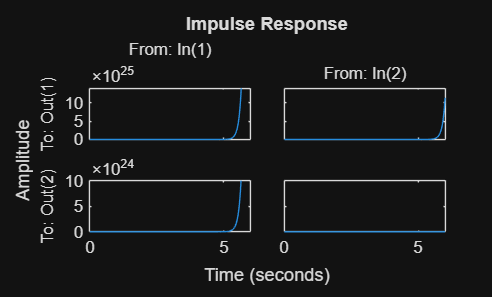


figure
impulse(T)


t = 0:0.01:20;

[wn, zeta, p] = damp(T)

wn =     6.0000
    6.0000
   10.0000
   10.0000


zeta =      1
     1
    -1
    -1


p =   -6.0000 + 0.0000i
  -6.0000 - 0.0000i
  10.0000 + 0.0000i
  10.0000 + 0.0000i



x_1 = [1;
       1;
       1;
       1]

x_1 =      1
     1
     1
     1



x_l = expm(A)

x_l = 1.0e+04 *

    5.5066    3.3040   -3.3040   -2.2026
    1.1013    1.1013   -1.1013    0.0000
    4.4053    2.2026   -2.2026   -2.2026
    1.1013    1.1013   -1.1013    0.0000


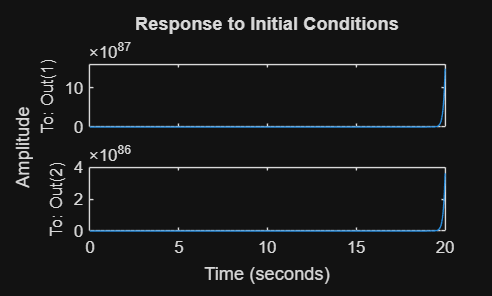


figure
initial(T,x_1,t)

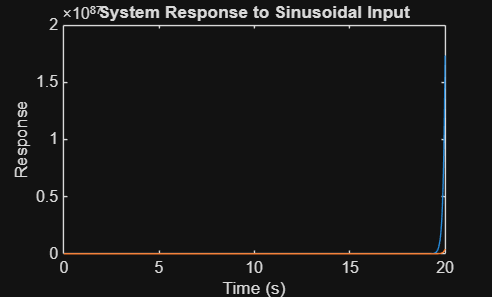


u2 = [sin(2*t) .* double(t >= 0);
      sin(2*t) .* double(t >= 0)];

y = lsim(T, u2, t);
figure
plot(t, y);
xlabel('Time (s)');
ylabel('Response');
title('System Response to Sinusoidal Input');


T_min = ss(T,'min')


T_min =
 
  A = 
           x1      x2
   x1   9.371  0.2585
   x2   -1.53   10.63
 
  B = 
           u1      u2
   x1  -2.506  0.5376
   x2   6.381   1.308
 
  C = 
             x1        x2
   y1  -0.02366    0.7742
   y2    -0.585    0.2404
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.


disp('Este sistemul stabil?');

Este sistemul stabil?


disp(eig(T_min.A))

  10.0000 + 0.0000i
  10.0000 - 0.0000i




F = -place(T_min.A,T_min.B,[-2 -2])

F =     2.3399   -0.9618
  -10.2455   -4.9629



disp(eig(T_min.A + T_min.B*F))

  -2.0000 + 0.0000i
  -2.0000 - 0.0000i




T_st = ss(T_min.A + T_min.B * F, T_min.B, T_min.C, T_min.D)


T_st =
 
  A = 
              x1         x2
   x1         -2  6.661e-16
   x2  -2.22e-15         -2
 
  B = 
           u1      u2
   x1  -2.506  0.5376
   x2   6.381   1.308
 
  C = 
             x1        x2
   y1  -0.02366    0.7742
   y2    -0.585    0.2404
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.



tf(T_st)


ans =
 
  From input 1 to output...
       s^2 + 9 s + 14
   1:  --------------
       s^2 + 4 s + 4
 
          3 s + 6
   2:  -------------
       s^2 + 4 s + 4
 
  From input 2 to output...
           s + 2
   1:  -------------
       s^2 + 4 s + 4
 
       s^2 + 4 s + 4
   2:  -------------
       s^2 + 4 s + 4
 
Continuous-time transfer function.


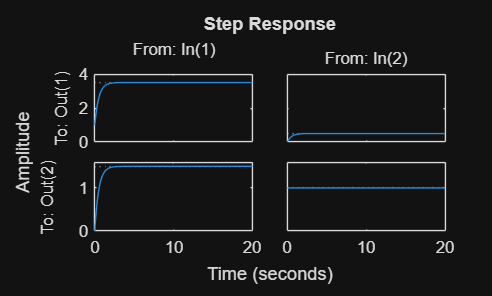


figure
step(T_st)

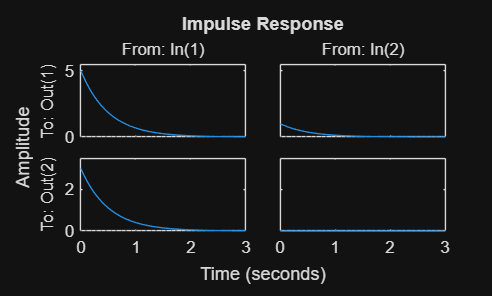


figure
impulse(T_st)

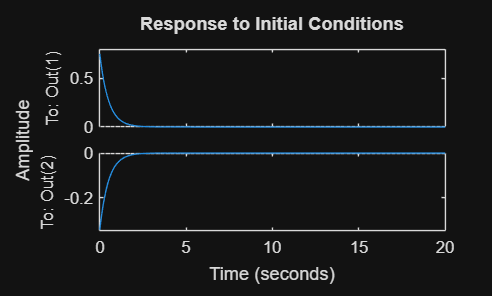


X_1st = [1;
         1];

figure
initial(T_st,X_1st,t)

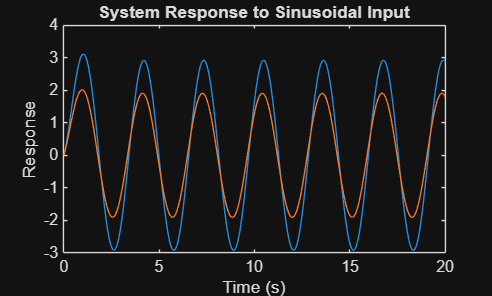


y = lsim(T_st, u2, t);
figure
plot(t, y);
xlabel('Time (s)');
ylabel('Response');
title('System Response to Sinusoidal Input');

sau LQR experimental

clear
close all
clc

A = [19 9 -9 -16;
     7 1 -7 2;
     16 0 -6 -14;
     8 8 -8 -6];

B = [5 1;
     3 0;
     2 1;
     3 0];

C = [-1 0 2 2;
      0 1 0 0];

D = eye(2);

Q = diag([10 9 12 9]);
R = diag([8 15]);

t = 0:0.01:20;

u2 = [sin(2*t) .* double(t >= 0);
      sin(2*t) .* double(t >= 0)];

K = lqr(A,B,Q,R);

disp(eig(A - B*K))

 -13.1300 + 0.0000i
  -9.3043 + 0.0000i
  -6.0000 + 0.0000i
  -6.0000 - 0.0000i




T_st = ss(A - B*K, B, C - D*K, D)


T_st =
 
  A = 
           x1      x2      x3      x4
   x1  -42.69   9.333  -10.78    44.5
   x2  -22.47  -1.789   -5.11   27.72
   x3  -16.22   3.123  -9.673   20.78
   x4  -21.47   5.211   -6.11   19.72
 
  B = 
       u1  u2
   x1   5   1
   x2   3   0
   x3   2   1
   x4   3   0
 
  C = 
            x1       x2       x3       x4
   y1   -10.82  -0.9298     2.63    10.57
   y2   -12.58    5.982   -4.933    17.63
 
  D = 
       u1  u2
   y1   1   0
   y2   0   1
 
Continuous-time state-space model.



tf(T_st)


ans =
 
  From input 1 to output...
       s^4 + 14.51 s^3 + 29.67 s^2 - 347.1 s - 1312
   1:  --------------------------------------------
       s^4 + 34.43 s^3 + 427.4 s^2 + 2274 s + 4398
 
         -1.903 s^3 - 56.33 s^2 - 470.5 s - 1206
   2:  -------------------------------------------
       s^4 + 34.43 s^3 + 427.4 s^2 + 2274 s + 4398
 
  From input 2 to output...
         -8.193 s^3 - 37.43 s^2 + 435.7 s + 2192
   1:  -------------------------------------------
       s^4 + 34.43 s^3 + 427.4 s^2 + 2274 s + 4398
 
       s^4 + 16.92 s^3 - 26.57 s^2 - 1283 s - 4380
   2:  -------------------------------------------
       s^4 + 34.43 s^3 + 427.4 s^2 + 2274 s + 4398
 
Continuous-time transfer function.


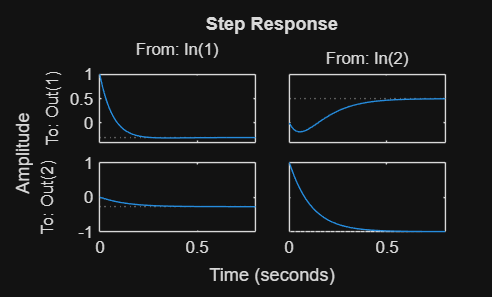


figure
step(T_st)

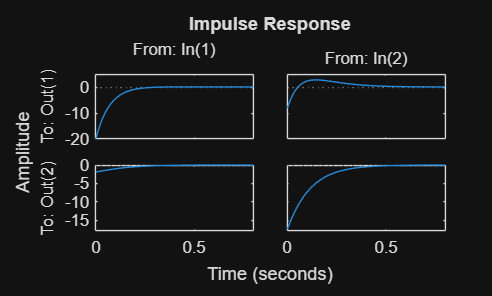


figure
impulse(T_st)

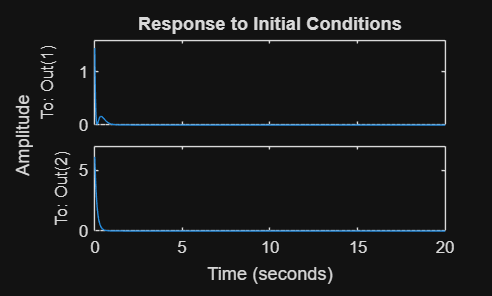


X_1st = [1;
         1;
         1;
         1];

figure
initial(T_st,X_1st,t)

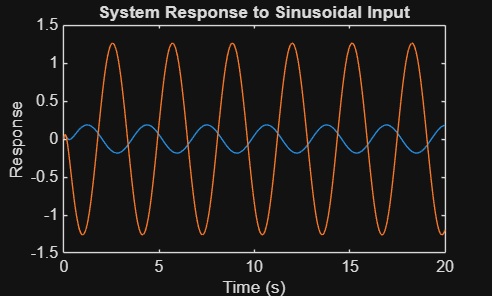


y = lsim(T_st, u2, t);
figure
plot(t, y);
xlabel('Time (s)');
ylabel('Response');
title('System Response to Sinusoidal Input');